# **倒立摆系统模型仿真**

## **一、参数设置**

#### 1.1 倒立摆/单摆物理参数及初始状态 PhyPara

clc;
clear all;
clear PhyPara;
clear TFPara;
  PhyPara.mp = 0.127;
  PhyPara.Lc=0.1685;
  PhyPara.Jp=0.0012;
  PhyPara.Bp=0.0024;
  PhyPara.Lr=0.216;
  PhyPara.Jr=0.001; 
  PhyPara.Br=0.0024;
  PhyPara.Rm=2.6;
  PhyPara.kt=7.68e-3;
  PhyPara.km=7.68e-3;
  PhyPara.Kg=70;
  PhyPara.eta_m=0.69;
  PhyPara.eta_g=0.9;
  PhyPara.g=9.8;
  PhyPara.AcFric = 0.4;
  
  InitX = [0,0,6,0]; %初始状态[theta0,theta0_dot,alpha0,alpha0_dot]

#### 1.2 仿真运行相关参数设置

  clear SimuRunInfo;
  SimuRunInfo.IdentTs = 0.002; %数据采样时间
  SimuRunInfo.TotalTime = 10; %仿真时间 

#### 1.3 激励信号设置 WaveFlag,1:方波;2:正弦,3:正弦叠加,4:自定义设置uin

  %用于时域辨识的激励信号设置
  clear UinSetIP;
  UinSetIP.WaveFlag = 1; %根据WaveFlag设置方波、正弦、正弦叠加等波形
  UinSetIP.Amp = 0.8;% %信号幅值
  UinSetIP.Fre = 0.8*2*pi;%信号频率
  UinSetIP.SumSinFreRange = [0.01,30]; %信号频率范围，用于频域辨识
  %用于频域辨识的激励信号设置
  clear UinSetFre; 
  UinSetFre.WaveFlag = 3; %trajdata
  UinSetFre.Amp = 10;
  UinSetFre.Fre = 15*pi;
  UinSetFre.SumSinFreRange = [0.01,10];%frequency range Hz should be less than 0.5/IdentTs
  clear UinSetCmp;
  UinSetCmp = UinSetIP; %用于线性非线性模型响应比较的输入信号，与时域辨识激励信号相同

#### 1.4 设置测量噪声和输入干扰信号，理想情况都设为0（To DO 辨识实验时，改变干扰参数）

 noiseTs=0.002; %噪声信号的采样周期 
 noisevar = 0;%0.1*pi/180; %噪声信号的方差
 disAmp = 0; %输入干扰的幅值
 disFre = 1; %输入干扰的频率
 disBias = 0;%输入干扰的相位
 DisturbPara.Dis = [disAmp,disFre,disBias];
             %[mean,variance,seed,noiseTs]
 DisturbPara.Noise = [0 noisevar 123 noiseTs%noise_theta
              0 noisevar 111 noiseTs%noise_thetadot
              0 noisevar 121 noiseTs%noise_alpha
              0 noisevar 113 noiseTs]; %noise_alphadot 

#### 1.5 辨识回归模型滤波器和辨识段数据设置（To DO 辨识实验时，改变滤波器参数）

  clear IdentSet;
  IdentSet.Filterwn = 15;%辨识用的两边同等滤波器的截止频率
  IdentSet.FilterZeta = 0.7;%辨识用的两边同等滤波器的阻尼比
  IdentSet.Difwn = 200; %微分滤波器的截止频率，用于直接求速度
  IdentSet.DifZeta = 1; %微分滤波器的阻尼比
  IdentSet.Alpha1Flag = 0; %是alpha1(顺摆)还是alpha(倒摆)角度？暂不用
 

#### 1.6 由物理参数获得数学模型参数

 [NominalPara] = Ident_GetTFParaFromPhyPara(PhyPara);
 [UinData] = Ident_SetDefaultUin(UinSetCmp,SimuRunInfo); %设置输入信号

## 二、倒立摆的线性与非线性模型响应比较

 %configure the parameters and simulate the model 
 ModelSelFlag = 3;
 %1：非线性倒立摆模型，ModelSelFlag=2；线性倒立摆模型，ModelSelFlag=3，非线性单摆模型，ModelSelFlag=4：线性单摆模型
 [SysResData]=Ident_SimulateRun(NominalPara,ModelSelFlag,UinData,InitX,DisturbPara,SimuRunInfo);

## 四、倒立摆/单摆的系统辨识实验(辨识作业待完成）

ModelSelFlag = 3; %选择单摆模型 0: rotary table without rod, 1:nonlinear IP, 2:linear IP,3 nonlinear Pendulum, 4:linear Pendulum
IdentSet.Alpha1Flag = 0; %倒摆
%在输入信号的激励下，进行单摆系统仿真
[IPResData] = Ident_SimulateRun(NominalPara,ModelSelFlag,UinData,InitX,DisturbPara,SimuRunInfo);

% 两边滤波处理
[FilterResData]=Ident_FilterRun(IPResData,IdentSet,SimuRunInfo,ModelSelFlag);
data = FilterResData;

t = data.time(:);
uin = data.uin_f(:);            % y1 (output) -> u (滤波后输入)
theta_dd = data.thetaddot_f(:); % θ̈ (滤波后)
theta_d  = data.thetadot_f(:);  % θ̇
alpha_dd = data.alphaddot_f(:); % α̈1
alpha_d  = data.alphadot_f(:);  % α̇1
alpha    = data.alpha_f(:);     % α1

% 如果前面滤波产生 transient/nan，可去掉开头若干样点
valid = ~isnan(uin) & ~isnan(theta_dd) & ~isnan(alpha_dd);
t = t(valid); uin = uin(valid); theta_dd = theta_dd(valid);
theta_d = theta_d(valid); alpha_dd = alpha_dd(valid);
alpha_d = alpha_d(valid); alpha = alpha(valid);

%% 1) Servo table dynamics 回归 （strict per image）
% 公式（图片）：
%   τ_t * θ̈ + θ̇ = K̄_t u(t) - K̄_t A_c * sign(θ̇) - K̄_t K̄_a α̈1
% 写成回归形式 u = φ1^T β1
% φ1 = [ θ̈, θ̇, sign(θ̇), α̈1 ]^T
% β1 = [ τ_t / K̄_t, 1 / K̄_t, A_c, K̄_a ]^T

Phi1 = [ theta_dd, theta_d, sign(theta_d), alpha_dd ]; % N x 4
y1   = uin;                                            % N x 1

% LSE 求解 β1
beta1 = (Phi1' * Phi1) \ (Phi1' * y1);

% 从 beta1 映射回物理量
% beta1 = [ tau_t / Kbar_t; 1 / Kbar_t; A_c; Kbar_a ]
beta_tau_over_Kbar = beta1(1);
beta_invKbar        = beta1(2);
beta_Ac             = beta1(3);
beta_Kabar          = beta1(4);

% 以 beta2 的第二分量求 Kbar_t（若 beta_invKbar 非零）
if abs(beta_invKbar) < eps
    warning('估计到 1/Kbar_t 非常小或为零，无法可靠反求 Kbar_t。保留 Nominal 值并继续。');
    Kbar_t_est = NominalPara.Kt; % fallback
else
    Kbar_t_est = 1 / beta_invKbar;
end
tau_t_est = beta_tau_over_Kbar * Kbar_t_est;
Ac_est    = beta_Ac;
Kabar_est = beta_Kabar;

%% 2) Rod dynamics 回归（strict per image）
% 图片公式（整理）：
%   α̈1 = - (L_t/g) ω_r^2 θ̈ - 2 ζ_r ω_r α̇1 - ω_r^2 α1
% => α̈1 = [ -θ̈, -α̇1, -α1 ] * [ (L_t/g) ω_r^2 ; 2 ζ_r ω_r ; ω_r^2 ]
% φ2 = [ -θ̈, -α̇1, -α1 ]^T
% β2 = [ (L_t/g) ω_r^2; 2 ζ_r ω_r; ω_r^2 ]^T

Phi2 = [ -theta_dd, -alpha_d, -alpha ]; % N x 3
y2   = alpha_dd;

beta2 = (Phi2' * Phi2) \ (Phi2' * y2);

% beta2 components
beta_Loverg_wr2 = beta2(1); % (L_t/g) * ω_r^2
beta_2zwr       = beta2(2); % 2 ζ_r ω_r
beta_wr2        = beta2(3); % ω_r^2

% 由 beta_wr2 求 ω_r
if beta_wr2 < 0
    warning('估计得到 ω_r^2 为负，取绝对值再开方以获得实数 ω_r（请检查数据）。');
    beta_wr2 = abs(beta_wr2);
end
wr_est = sqrt(beta_wr2);

% 阻尼比 ζ_r
if wr_est ~= 0
    zeta_r_est = beta_2zwr / (2 * wr_est);
else
    zeta_r_est = NaN;
end

% 由 beta_Loverg_wr2 求 L_t/g
if beta_wr2 ~= 0
    Loverg_est = beta_Loverg_wr2 / beta_wr2; % = (L_t/g)
else
    Loverg_est = NaN;
end

%% 3) 把估计结果写回 IdentifyPara 以供仿真验证
% 先基于 NominalPara 拷贝（保证其它字段完整），然后覆盖估计项
IdentifyPara = NominalPara; % 保留未估计的字段
% Servo 表面参数
IdentifyPara.Taot = tau_t_est;     % τ_t (time-constant-like)
IdentifyPara.Kt   = Kbar_t_est;    % K̄_t
IdentifyPara.Ac   = Ac_est;         % Coulomb 摩擦幅值
% 图片中 K̄_a 是耦合项（对应 α̈1 的系数）
% 在 Ident_GetTFParaFromPhyPara 中 Ka = mp*Lr*Lc/Ku （名字可能不同），
% 这里我们直接写一个字段 Kabar，以便 simulink/标识使用（若 Simulink 期望字段为 Ka，请根据模型改名）
IdentifyPara.Ka = Kabar_est;

% rod 参数
IdentifyPara.wr = wr_est;
IdentifyPara.kesair = zeta_r_est;   % 在你原变量中 kesair 代表阻尼比相关项
% TFPara 中 Kr 是 Lr/g（见 Ident_GetTFParaFromPhyPara），这里也写入 Kr
IdentifyPara.Kr = Loverg_est;

% 辅助（使得仿真能够顺利运行）
IdentifyPara.wt = 1 / max(eps, IdentifyPara.Taot); % wt = 1/Taot
IdentifyPara.deta_alpha = 0;
IdentifyPara.deta_theta = 0;

% 显示估计结果
disp('===== 识别结果（按图片回归映射） =====');

===== 识别结果（按图片回归映射） =====


fprintf('Kbar_t (K̄_t) = %.6f\n', IdentifyPara.Kt);

Kbar_t (K̄_t) = 53.333597


fprintf('tau_t (τ_t) = %.6f\n', IdentifyPara.Taot);

tau_t (τ_t) = 0.083625


fprintf('Ac = %.6f\n', IdentifyPara.Ac);

Ac = 0.045274


fprintf('Kabar (K̄_a) = %.6f\n', IdentifyPara.Ka);

Kabar (K̄_a) = 0.001052


fprintf('wr = %.6f (rad/s), kesair (zeta) = %.6f\n', IdentifyPara.wr, IdentifyPara.kesair);

wr = 6.695530 (rad/s), kesair (zeta) = 0.006218


fprintf('L_t/g (Kr) = %.6f\n', IdentifyPara.Kr);

L_t/g (Kr) = 0.021623



%% 4) 仿真验证：用 IdentifyPara 做一次仿真并比较
[IPIdentVerifyData] = Ident_SimulateRun(IdentifyPara, ModelSelFlag, UinData, InitX, DisturbPara, SimuRunInfo);

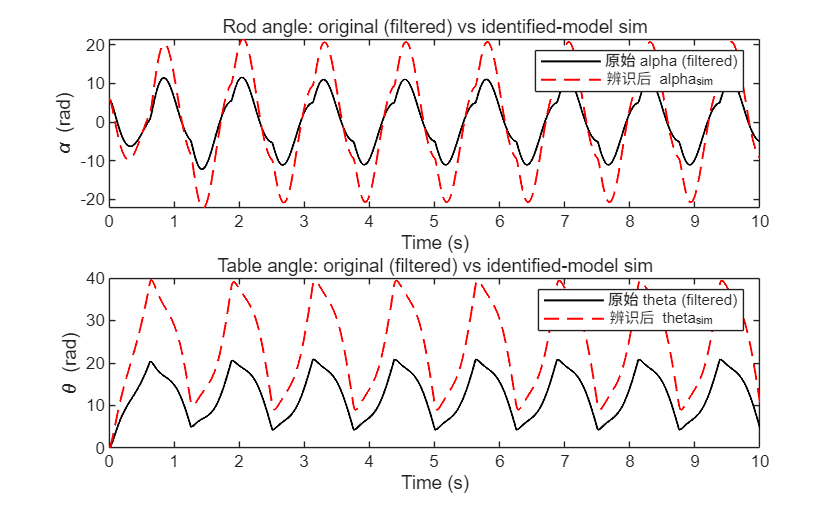


% 画图比较（用滤波后原始信号 vs 识别模型仿真）
figure;
subplot(2,1,1);
plot(data.time, data.alpha, 'k', IPIdentVerifyData.time, IPIdentVerifyData.alpha, '--r','LineWidth',1);
legend('原始 alpha (filtered)','辨识后 alpha_{sim}');
xlabel('Time (s)'); ylabel('\alpha (rad)');
title('Rod angle: original (filtered) vs identified-model sim');

subplot(2,1,2);
plot(data.time, data.theta, 'k', IPIdentVerifyData.time, IPIdentVerifyData.theta, '--r','LineWidth',1);
legend('原始 theta (filtered)','辨识后 theta_{sim}');
xlabel('Time (s)'); ylabel('\theta (rad)');
title('Table angle: original (filtered) vs identified-model sim');

###  子函数：获得传递函数模型参数Ident_GetTFParaFromPhyPara

 function [TFPara] = Ident_GetTFParaFromPhyPara(PhyPara)
    mp = PhyPara.mp;
    Lc = PhyPara.Lc;
    Jp = PhyPara.Jp;
    Bp = PhyPara.Bp;
    Lr = PhyPara.Lr;
    Jeq = PhyPara.Jr;
    Beq = PhyPara.Br;
    Rm = PhyPara.Rm;
    kt = PhyPara.kt;
    km = PhyPara.km;
    Kg = PhyPara.Kg;
    yitam = PhyPara.eta_m;
    yitag = PhyPara.eta_g;
    Accg = PhyPara.g;
    Ac = PhyPara.AcFric;
    
     Jr = Jeq;
     Ip = Jp + mp*Lc^2; %A1
     It = Jr + mp*Lr^2; %B1
     Ku = yitam*yitag*kt*Kg/Rm; %B2
     Br = (yitam*yitag*kt*km*Kg^2+Beq*Rm)/Rm; %Beq;
     clear TFPara;
     TFPara = PhyPara;
     TFPara.Kt = Ku/Br;
     TFPara.Taot = It/Br;
     TFPara.Ac = Ac;
     TFPara.Ka = mp*Lr*Lc/Ku;
     TFPara.wr = sqrt(mp*Accg*Lc/Ip);
     TFPara.kesair = sqrt(Bp^2/(4*Ip*mp*Accg*Lc));
     TFPara.wt = 1/TFPara.Taot;
     TFPara.Kr = Lr/Accg;
     TFPara.deta_alpha = 0;
     TFPara.deta_theta = 0;
 end

### 子函数：设置激励信号 Ident_SetDefaultUin

#### （UinSet.WaveFlag,1:方波，2：正弦，3：正弦叠加,4:自定义）

function [UinData] = Ident_SetDefaultUin(UinSet,SimuRunInfo)
  clear UinData;
  %输入正弦信号参数
    UinData.Sin =[1,4*pi,0];%[amp,fre,bias].Amp = 1;%0-2-6;
  %输入方波信号参数 
    UinData.Square = [5,15*pi,0]; %[amp,fre,bias]
  %辨识激励信号(正弦叠加信号)的设置 
    IdentTs = SimuRunInfo.IdentTs;
    identN = 2*floor(SimuRunInfo.TotalTime/IdentTs);%10000; %系统辨识的数据个数
    Identtraj = idinput([identN 1 1],'sine',[0,1],[-1,1],[500 50 1]);
    tout = 0:IdentTs:identN*IdentTs-IdentTs;
    UinData.IdentTrajData.time = tout'; %正弦叠加的辨识激励信号
    UinData.IdentTrajData.signals.values = Identtraj;
    UinData.IdentTrajData.dimensions = 1;
   %选择波形类型  
    UinData.WaveFlag = UinSet.WaveFlag;
  switch (UinSet.WaveFlag)
      case {1} %square
          UinData.Square = [UinSet.Amp,UinSet.Fre,0];%[amp,fre,bias]
      case {2} % uinsin
          UinData.Sin = [UinSet.Amp,UinSet.Fre,0];
      case {3}  %sumsinusoidal
         SumSinFreRange = UinSet.SumSinFreRange/(0.5/IdentTs);
         SumSinAmpRange = [-UinSet.Amp,UinSet.Amp]; %辨识激励信号的范围;
         sumnumber = UinSet.SumSinFreRange(2)*7.5;
         Identtraj = idinput([identN 1 1],'sine',SumSinFreRange,SumSinAmpRange,[sumnumber 50 1]);
         tout = 0:IdentTs:identN*IdentTs-IdentTs;
         UinData.IdentTrajData.time = tout'; %正弦叠加的辨识激励信号
         UinData.IdentTrajData.signals.values = Identtraj;
         UinData.IdentTrajData.dimensions = 1;
      case {4} %custom define uin
        UinData.IdentTrajData.time = UinSet.time;%正弦叠加的辨识激励信号
        UinData.IdentTrajData.signals.values = UinSet.uin;
        UinData.IdentTrajData.dimensions = 1;
        UinData.WaveFlag = 3;
  end
end

### 子函数：仿真模型的时域响应 Ident_SimulateRun

function [SysResData]=Ident_SimulateRun(TFPara,ModelSelFlag,UinData,InitX,DisturbPara,SimuRunInfo)
 
  switch ModelSelFlag 
      case 0 %servo table without rod
       ModelSelFlagNonlin = ModelSelFlag;
       ModelSelFlagLin = ModelSelFlag;
      case {1,2} %Inverted Pendulum
       ModelSelFlagNonlin = ModelSelFlag;
       ModelSelFlagLin = 2;   
     case {3,4} %Pendulum
       ModelSelFlagNonlin = ModelSelFlag;
       ModelSelFlagLin = 4;   
 end
  assignin('base', 'WaveFlag',UinData.WaveFlag); 
  assignin('base', 'TFPara',TFPara); 
  assignin('base', 'ModelSelFlagNonlin',ModelSelFlagNonlin);
  assignin('base', 'ModelSelFlagLin',ModelSelFlagLin);
  assignin('base', 'InitX',InitX);  
  assignin('base', 'IdentTs',SimuRunInfo.IdentTs);  
  assignin('base', 'UinSquare',UinData.Square);  
  assignin('base', 'UinSin',UinData.Sin);  
  assignin('base', 'IdentTrajData',UinData.IdentTrajData);  
  assignin('base', 'UinDis',DisturbPara.Dis); 
  assignin('base', 'NoisePara',DisturbPara.Noise); 
  sim('MIC_Mdl_Inverted_Pendulum.slx',SimuRunInfo.TotalTime); %simulink 仿真
    y1 = ResponseData.signals.values;
    t1 = ResponseData.time; 
    clear SysResData;
    %记录响应数据
    SysResData.time = t1;
    SysResData.uin = y1(:,1);
    SysResData.theta = y1(:,2);
    SysResData.thetadot = y1(:,3);
    SysResData.alpha = y1(:,4);
    SysResData.alphadot = y1(:,5);
   
    SysResData.theta_Lin = y1(:,6);
    SysResData.thetadot_Lin = y1(:,7);
    SysResData.alpha_Lin = y1(:,8);
    SysResData.alphadot_Lin = y1(:,9);
end

### 子函数：辨识时的两边滤波处理 Ident_FilterRun

function [FilterResData]=Ident_FilterRun(ResData,IdentSet,SimuRunInfo,ModelSelFlag)
 if(ModelSelFlag ==1)
    Alpha1Flag = 1; 
 else
    Alpha1Flag = 0;
 end
  clear OriResData;
  OriResData.time = ResData.time;
  OriResData.signals.values = [ResData.uin ResData.alpha ResData.theta ResData.alphadot  ResData.thetadot];%[u2,alpha2,theta2];
  OriResData.signals.dimensions = 5;
  assignin('base', 'OriResData',OriResData); 
  assignin('base', 'Difwn',IdentSet.Difwn); 
  assignin('base', 'DifZeta',IdentSet.DifZeta);  
  assignin('base', 'Alpha1Flag',Alpha1Flag); 
  assignin('base', 'Identwn',IdentSet.Filterwn); 
  assignin('base', 'IdentZeta',IdentSet.FilterZeta);
  assignin('base', 'IdentTs',SimuRunInfo.IdentTs);  

  sim('MIC_Mdl_IdentFilter.slx',SimuRunInfo.TotalTime); %simulink 仿真
    y1 = IdentFilterData.signals.values;
    t1 = IdentFilterData.time; 
    clear FilterResData;
    FilterResData.time = t1;
    FilterResData.uin_f = y1(:,1);
    FilterResData.alpha_f = y1(:,2);
    FilterResData.alphadot_f = y1(:,3);
    FilterResData.alphaddot_f = y1(:,4);
    FilterResData.signalphadot_f = y1(:,5);
    FilterResData.one_f = y1(:,6);
    FilterResData.theta_f = y1(:,7);
    FilterResData.thetadot_f = y1(:,8);
    FilterResData.thetaddot_f = y1(:,9);
    FilterResData.signthetadot_f = y1(:,10);
    FilterResData.uin = y1(:,11);
    FilterResData.alpha = y1(:,12);
    FilterResData.theta = y1(:,13);
    FilterResData.alphadot = y1(:,14);
    FilterResData.thetadot = y1(:,15);
end